### Model Extension 2: Stochastic Life Cycle Model with Endogenous Labor

### Fit the simulated data and real data

This file compares the simulated and real data of the extension stochastic model

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 



### Check for sensitivity of the model (with simulated data)

par = model2.setup; % Set parameters.
par = model2.gen_grids(par); % Generate the state space.
t = cputime;
sol = solve2.lc(par); % Solve the model using Value Function Iteration.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 88.5938 seconds.


sim = simulate2.lc(par,sol); % Simulate the model.

### Sensitivity in individuals' utility, i.e., $\gamma$ and $\nu$

Params used to examine the are coefficient and preference about labor supply choice:

- $\gamma$:  **Weight on leisure** - Higher values mean that leisure has a higher weight in the utility function

- $\nu$: **Frisch Elasticity** - Higher values of this mean that the labor choice becomes more sensitive to productivity shocks

% Define parameter values for sensitivity analysis
gamma_vals = [1.0, 3.0, 5.0];
nu_vals = [0.5, 1.5, 2.5];

% Loop over all combinations of gamma and nu
% Create figure with 2 subplots
figure;
colors = lines(length(gamma_vals));

% Initialize storage for all lines
cons_data = nan(length(gamma_vals), 100); % Assuming T ≤ 100
asset_data = nan(length(gamma_vals), 100);
labor_data = nan(length(gamma_vals), 100);
T_max = 0;

for i = 1:length(gamma_vals)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.gamma = gamma_vals(i);
    par.nu = 1.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    % Initialize storage
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), 'omitnan');
    end

    % Store data for plotting
    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;
    labor_data(i,1:par.T) = lcp_n;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


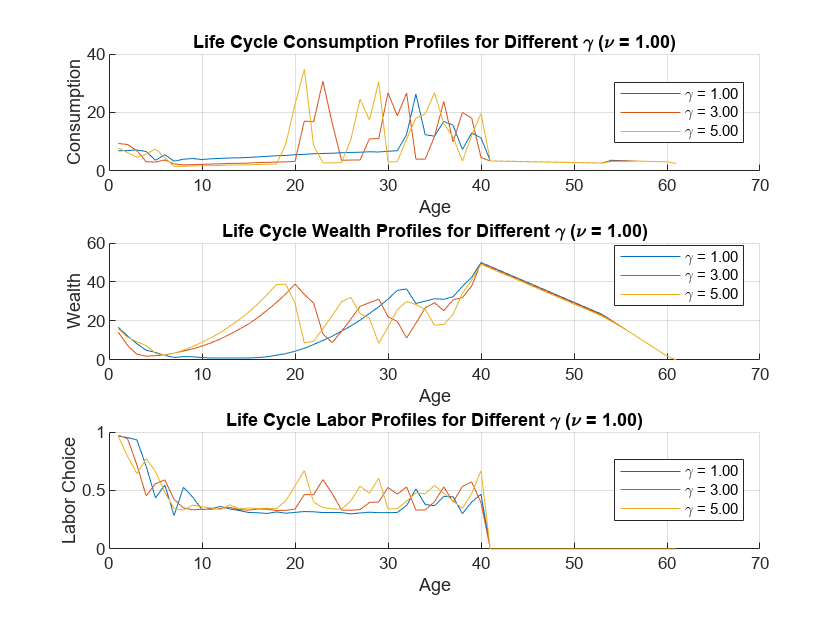


%% Subplot 1: Consumption
subplot(3,1,1);
hold on;
for i = 1:length(gamma_vals)
    plot(1:T_max, cons_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(i)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \gamma (\nu = 1.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(3,1,2);
hold on;
for i = 1:length(gamma_vals)
    plot(1:T_max, asset_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(i)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \gamma (\nu = 1.00)');
legend('show', 'Location', 'best');
grid on;
hold off;
%% Subplot 3: Labor Choice
subplot(3,1,3);
hold on;
for i = 1:length(gamma_vals)
    plot(1:T_max, labor_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(i)));
end
xlabel('Age');
ylabel('Labor Choice');
title('Life Cycle Labor Profiles for Different \gamma (\nu = 1.00)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim7.png'))



%% Plot life cycle profiles for different nu values
% Create figure with 3 subplots
figure;
colors = lines(length(nu_vals));

% Storage for max age
T_max = 0;
cons_data = nan(length(nu_vals), 100); % Assuming max T ≤ 100
asset_data = nan(length(nu_vals), 100);
labor_data = nan(length(nu_vals), 100);


for j = 1:length(nu_vals)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.nu = nu_vals(j);
    par.gamma = 2.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
        lcp_n(t) = mean(sim.nsim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;
    labor_data(j,1:par.T) = lcp_n;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


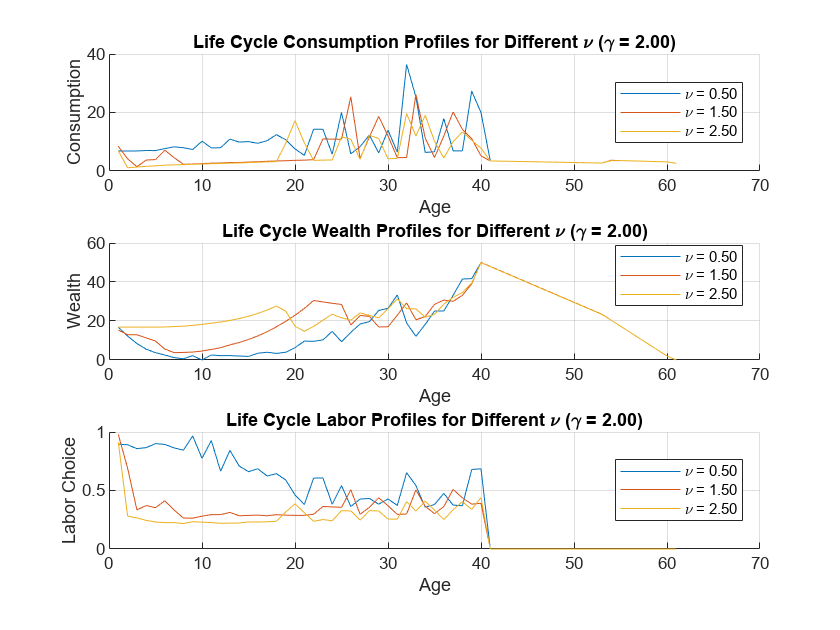


%% Subplot 1: Consumption
subplot(3,1,1);
hold on;
for j = 1:length(nu_vals)
    plot(1:T_max, cons_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\nu = %.2f', nu_vals(j)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \nu (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(3,1,2);
hold on;
for j = 1:length(nu_vals)
    plot(1:T_max, asset_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\nu = %.2f', nu_vals(j)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \nu (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 3: Labor Choice
subplot(3,1,3);
hold on;
for j = 1:length(nu_vals)
    plot(1:T_max, labor_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\nu = %.2f', nu_vals(j)));
end
xlabel('Age');
ylabel('Labor Choice');
title('Life Cycle Labor Profiles for Different \nu (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim8.png'))


%% Compute and plot heatmap of average simulated wealth
avg_wealth = nan(length(gamma_vals), length(nu_vals)); % Ensure NaN initialization

for i = 1:length(gamma_vals)
    for j = 1:length(nu_vals)
        % Initialize and update parameters
        par = model2.setup;
        par = model2.gen_grids(par);
        par.gamma = gamma_vals(i);
        par.nu = nu_vals(j);

        % Solve model for given parameters
        sol = solve2.lc(par);
        sim = simulate2.lc(par, sol);

        % Compute average wealth
        avg_wealth(i,j) = mean(sim.asim(:), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

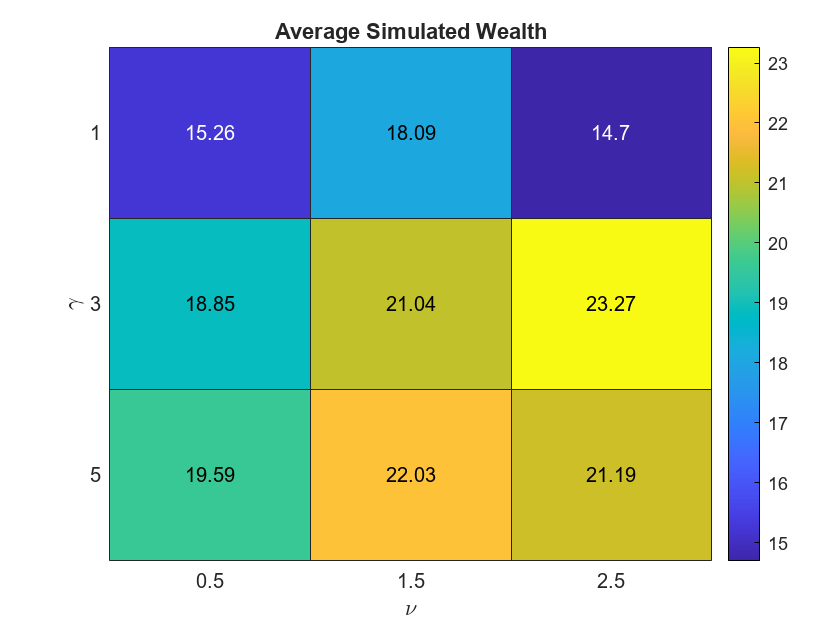


% Create heatmap
figure;
h = heatmap(string(nu_vals), string(gamma_vals), avg_wealth, 'Colormap', parula);
xlabel('\nu');
ylabel('\gamma');
title('Average Simulated Wealth');
saveas(gcf, fullfile(figout, 'sim9.png'))

### Descriptive Statistics 

%% Define parameter values
gamma_vals = [1.0, 3.0, 5.0];
nu_vals = [0.5, 1.5, 2.5];

% Initialize storage for all data
cons_data = nan(length(gamma_vals), 100);  % Assuming T_max ≤ 100
asset_data = nan(length(gamma_vals), 100);
labor_data = nan(length(gamma_vals), 100);
T_max = 0;

% Initialize structure for storing descriptive statistics
descriptive_stats = struct();

%% Loop over different betas to calculate consumption and wealth
for i = 1:length(gamma_vals)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.gamma = gamma_vals(i);
    par.nu = 1.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), 'omitnan');
    end

    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;
    labor_data(i,1:par.T) = lcp_n;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(i, 1:T_max), 'omitnan');
    cons_std = std(cons_data(i, 1:T_max), 'omitnan');
    cons_min = min(cons_data(i, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(i, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(i, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.gamma(i).cons_mean = cons_mean;
    descriptive_stats.gamma(i).cons_std = cons_std;
    descriptive_stats.gamma(i).cons_min = cons_min;
    descriptive_stats.gamma(i).cons_max = cons_max;
    descriptive_stats.gamma(i).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(i, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(i, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(i, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.gamma(i).wealth_mean = wealth_mean;
    descriptive_stats.gamma(i).wealth_std = wealth_std;
    descriptive_stats.gamma(i).wealth_min = wealth_min;
    descriptive_stats.gamma(i).wealth_max = wealth_max;
    descriptive_stats.gamma(i).wealth_median = wealth_median;

    % Calculate descriptive statistics for wealth
    labor_mean = mean(labor_data(i, 1:T_max), 'omitnan');
    labor_std = std(labor_data(i, 1:T_max), 'omitnan');
    labor_min = min(labor_data(i, 1:T_max), [], 'omitnan');
    labor_max = max(labor_data(i, 1:T_max), [], 'omitnan');
    labor_median = median(labor_data(i, 1:T_max), 'omitnan');

    % Store statistics for labor
    descriptive_stats.gamma(i).labor_mean = labor_mean;
    descriptive_stats.gamma(i).labor_std = labor_std;
    descriptive_stats.gamma(i).labor_min = labor_min;
    descriptive_stats.gamma(i).labor_max = labor_max;
    descriptive_stats.gamma(i).labor_median = labor_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



%% Display Descriptive Statistics for Consumption
cons_table = table();
cons_table.Gamma = gamma_vals';
cons_table.Mean = [descriptive_stats.gamma(:).cons_mean]';
cons_table.StdDev = [descriptive_stats.gamma(:).cons_std]';
cons_table.Min = [descriptive_stats.gamma(:).cons_min]';
cons_table.Max = [descriptive_stats.gamma(:).cons_max]';
cons_table.Median = [descriptive_stats.gamma(:).cons_median]';

disp('Descriptive Statistics for Consumption for different values of gammas:');

Descriptive Statistics for Consumption for different values of gammas:


disp(cons_table);

    Gamma     Mean     StdDev     Min       Max      Median
    _____    ______    ______    ______    ______    ______

      1      5.9651    4.1645     2.618    26.314     4.641
      3       6.906    7.1755    2.0984    30.725    3.3099
      5      7.1657    7.8822    1.5679    34.849    3.2326



%% Display Descriptive Statistics for Wealth
wealth_table = table();
wealth_table.Gamma = gamma_vals';
wealth_table.Mean = [descriptive_stats.gamma(:).wealth_mean]';
wealth_table.StdDev = [descriptive_stats.gamma(:).wealth_std]';
wealth_table.Min = [descriptive_stats.gamma(:).wealth_min]';
wealth_table.Max = [descriptive_stats.gamma(:).wealth_max]';
wealth_table.Median = [descriptive_stats.gamma(:).wealth_median]';

disp('Descriptive Statistics for Wealth for different values of gammas:');

Descriptive Statistics for Wealth for different values of gammas:


disp(wealth_table);

    Gamma     Mean     StdDev    Min     Max      Median
    _____    ______    ______    ___    ______    ______

      1      18.744    15.452     0         50    16.837
      3      21.658    13.278     0     49.694    21.735
      5      22.066    12.826     0     49.082    22.551





%% Display Descriptive Statistics for Labor
labor_table = table();
labor_table.Gamma = gamma_vals';
labor_table.Mean = [descriptive_stats.gamma(:).labor_mean]';
labor_table.StdDev = [descriptive_stats.gamma(:).labor_std]';
labor_table.Min = [descriptive_stats.gamma(:).labor_min]';
labor_table.Max = [descriptive_stats.gamma(:).labor_max]';
labor_table.Median = [descriptive_stats.gamma(:).labor_median]';

disp('Descriptive Statistics for Labor Choice for different values of gammas:');

Descriptive Statistics for Labor Choice for different values of gammas:


disp(labor_table);

    Gamma     Mean      StdDev     Min      Max      Median 
    _____    _______    _______    ___    _______    _______

      1      0.27067    0.24426     0     0.96479    0.31115
      3      0.29362    0.24773     0     0.97065    0.33715
      5      0.30472    0.25415     0     0.96325    0.34622





%% Loop over different nus to calculate consumption, wealth, and labor
cons_data = nan(length(nu_vals), 100);  % Reset storage for consumption data
asset_data = nan(length(nu_vals), 100);  % Reset storage for asset data
labor_data = nan(length(nu_vals), 100);  % Reset storage for asset data
T_max = 0;

for j = 1:length(nu_vals)
    par = model2.setup;
    par = model2.gen_grids(par); 
    par.nu = nu_vals(j);
    par.gamma = 2.00;
    sol = solve2.lc(par);
    sim = simulate2.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
        lcp_n(t) = mean(sim.nsim(indices), 'omitnan');

    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;
    labor_data(j,1:par.T) = lcp_n;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(j, 1:T_max), 'omitnan');
    cons_std = std(cons_data(j, 1:T_max), 'omitnan');
    cons_min = min(cons_data(j, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(j, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(j, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.nu(j).cons_mean = cons_mean;
    descriptive_stats.nu(j).cons_std = cons_std;
    descriptive_stats.nu(j).cons_min = cons_min;
    descriptive_stats.nu(j).cons_max = cons_max;
    descriptive_stats.nu(j).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(j, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(j, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(j, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.nu(j).wealth_mean = wealth_mean;
    descriptive_stats.nu(j).wealth_std = wealth_std;
    descriptive_stats.nu(j).wealth_min = wealth_min;
    descriptive_stats.nu(j).wealth_max = wealth_max;
    descriptive_stats.nu(j).wealth_median = wealth_median;

    % Calculate descriptive statistics for labor
    labor_mean = mean(labor_data(j, 1:T_max), 'omitnan');
    labor_std = std(labor_data(j, 1:T_max), 'omitnan');
    labor_min = min(labor_data(j, 1:T_max), [], 'omitnan');
    labor_max = max(labor_data(j, 1:T_max), [], 'omitnan');
    labor_median = median(labor_data(j, 1:T_max), 'omitnan');

    % Store statistics for labor
    descriptive_stats.nu(j).labor_mean = labor_mean;
    descriptive_stats.nu(j).labor_std = labor_std;
    descriptive_stats.nu(j).labor_min = labor_min;
    descriptive_stats.nu(j).labor_max = labor_max;
    descriptive_stats.nu(j).labor_median = labor_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


%% Display Descriptive Statistics for Consumption
consp_table = table();
consp_table.Nu = nu_vals';
consp_table.Mean = [descriptive_stats.nu(:).cons_mean]';
consp_table.StdDev = [descriptive_stats.nu(:).cons_std]';
consp_table.Min = [descriptive_stats.nu(:).cons_min]';
consp_table.Max = [descriptive_stats.nu(:).cons_max]';
consp_table.Median = [descriptive_stats.nu(:).cons_median]';

disp('Descriptive Statistics for Consumption:');

Descriptive Statistics for Consumption:


disp(consp_table);

    Nu      Mean     StdDev     Min       Max      Median
    ___    ______    ______    ______    ______    ______

    0.5    8.2973    6.5612     2.618    36.463    6.8524
    1.5    5.9744    5.4709    1.4725    26.149    3.4773
    2.5    5.3345    4.4456    1.1086    19.666     3.299





%% Display Descriptive Statistics for Wealth
wealth_table = table();
wealth_table.Nu = nu_vals';
wealth_table.Mean = [descriptive_stats.nu(:).wealth_mean]';
wealth_table.StdDev = [descriptive_stats.nu(:).wealth_std]';
wealth_table.Min = [descriptive_stats.nu(:).wealth_min]';
wealth_table.Max = [descriptive_stats.nu(:).wealth_max]';
wealth_table.Median = [descriptive_stats.nu(:).wealth_median]';

disp('Descriptive Statistics for Wealth:');

Descriptive Statistics for Wealth:


disp(wealth_table);

    Nu      Mean     StdDev    Min     Max      Median
    ___    ______    ______    ___    ______    ______

    0.5    17.799    14.719     0         50    14.286
    1.5    21.325    12.728     0         50    20.612
    2.5    23.968    10.369     0     49.898    22.449



%% Display Descriptive Statistics for Labor
labor_table = table();
labor_table.Nu = nu_vals';
labor_table.Mean = [descriptive_stats.nu(:).labor_mean]';
labor_table.StdDev = [descriptive_stats.nu(:).labor_std]';
labor_table.Min = [descriptive_stats.nu(:).labor_min]';
labor_table.Max = [descriptive_stats.nu(:).labor_max]';
labor_table.Median = [descriptive_stats.nu(:).labor_median]';

disp('Descriptive Statistics for Labor:');

Descriptive Statistics for Labor:


disp(labor_table);

    Nu      Mean      StdDev     Min      Max      Median 
    ___    _______    _______    ___    _______    _______

    0.5    0.41004    0.34018     0     0.96654    0.42717
    1.5    0.24066    0.20518     0     0.97982    0.28952
    2.5    0.19566    0.17167     0     0.91315    0.23063



Unrecognized function or variable 'gamma_stats'.

### Import the real data

We import the dataset $\texttt{data\_processed}$ containing average household consumption and total household wealth. We calculate the average of the two features by age group and compare the descriptive statistics of the simulated and real data. 

clc;
clearvars -except sim par main;
close all;

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 




%% Load the real data
real_data = readtable(fullfile(main, 'data_process.csv'));

% Check column names
disp(real_data.Properties.VariableNames)

  Columns 1 through 11

    {'tinh'}    {'huyen'}    {'xa'}    {'diaban'}    {'hoso'}    {'matv'}    {'hsize'}    {'m1ac2'}    {'m1ac3'}    {'age'}    {'indi_income'}

  Columns 12 through 17

    {'HH_Income'}    {'hsize_working'}    {'indi_work_hours'}    {'hh_work_hours'}    {'avg_work_hours'}    {'HH_consumption'}

  Columns 18 through 19

    {'HH_consumption_…'}    {'HH_Wealth'}



real_grouped = grpstats(real_data, 'age', {'mean'}, 'DataVars', {'HH_Wealth', 'HH_consumption_avr', 'avg_work_hours', 'HH_Income'});

% Rename variables for clarity
real_grouped.Properties.VariableNames{'mean_HH_Wealth'} = 'mean_HH_Wealth';
real_grouped.Properties.VariableNames{'mean_HH_consumption_avr'} = 'mean_HH_consumption_avr';
real_grouped.Properties.VariableNames{'mean_avg_work_hours'} = 'mean_avg_work_hours';

num_real_ages = height(real_grouped);
real_age = (1:num_real_ages)';
real_c = real_grouped.mean_HH_consumption_avr;
real_a = real_grouped.mean_HH_Wealth;
real_n = real_grouped.mean_avg_work_hours;

% Calculate the total possible work hours annually without any leisure
total_hours = 260 * 16;

% Normalize by first data point (age 1 or the first age in the dataset)
real_c_norm = real_c / real_c(1);
real_a_norm = real_a / real_a(1);
real_n_norm = real_n / total_hours;

### Visualize the simulated and real data

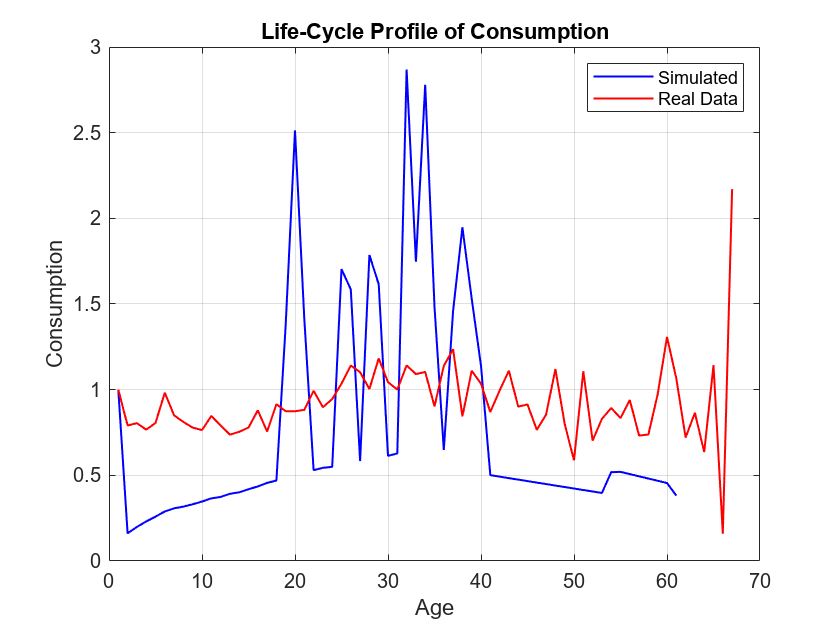

%% Simulated data: average across individuals by age
sim_age = linspace(1, par.T, par.T)';
sim_c = nan(par.T,1);
sim_a = nan(par.T,1);
sim_n = nan(par.T,1);

for t = 1:par.T
    sim_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    sim_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    sim_n(t) = mean(sim.nsim(sim.tsim == t), 'omitnan');
end

%% Plot comparison: Consumption
figure;
plot(sim_age, sim_c/sim_c(1), '-b', 'LineWidth', 1); hold on;
plot(real_age, real_c_norm, 'r', 'LineWidth', 1);
xlabel('Age');
ylabel('Consumption');
legend('Simulated', 'Real Data');
title('Life-Cycle Profile of Consumption');
saveas(gcf, fullfile(figout, 'sim10.png'))
grid on;

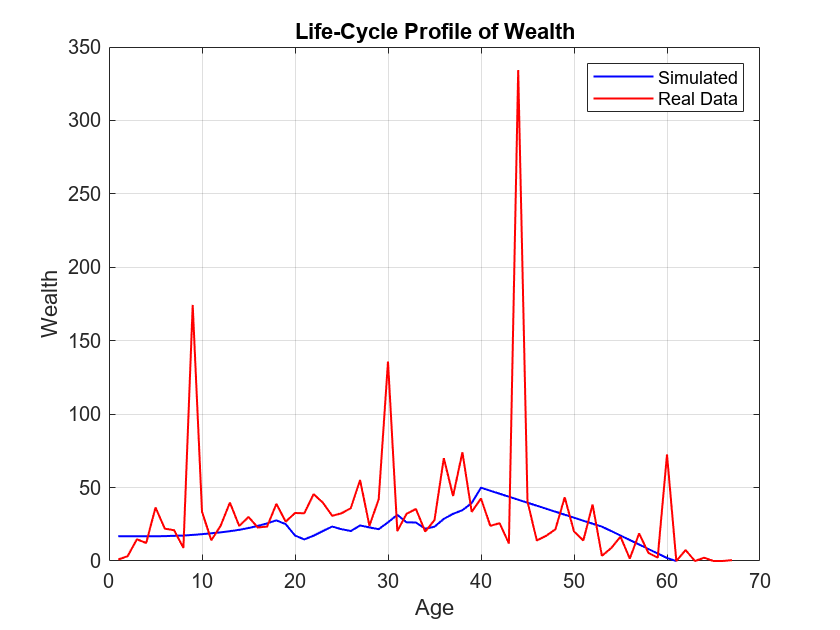


%% Plot comparison: Wealth
figure;
plot(sim_age, sim_a, '-b', 'LineWidth', 1); hold on;
plot(real_age, real_a_norm, '-r', 'LineWidth', 1);
xlabel('Age');
ylabel('Wealth');
legend('Simulated', 'Real Data');
title('Life-Cycle Profile of Wealth');
saveas(gcf, fullfile(figout, 'sim11.png'))
grid on

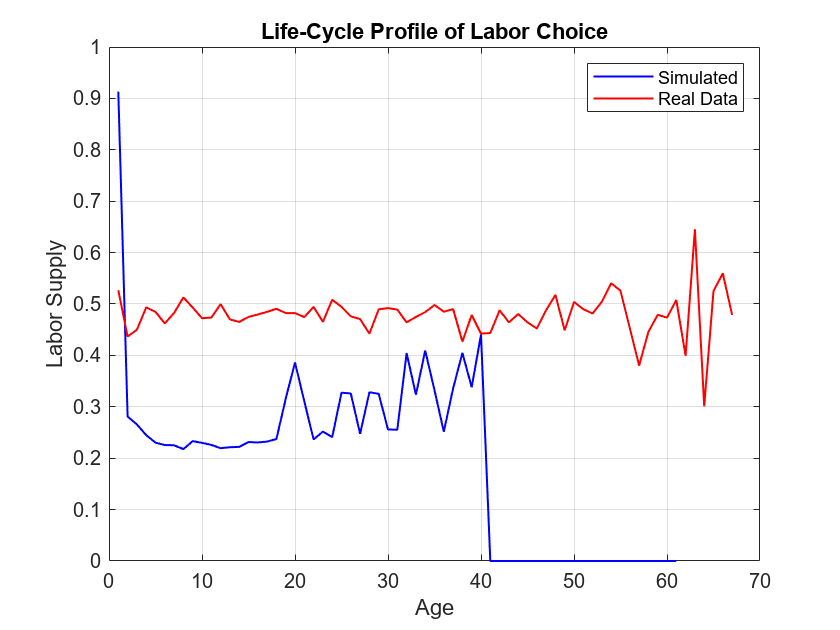

%% Plot comparison: Labor Supply
figure;
plot(sim_age, sim_n, '-b', 'LineWidth', 1); hold on;
plot(real_age, real_n_norm, '-r', 'LineWidth', 1);
xlabel('Age');
ylabel('Labor Supply');
legend('Simulated', 'Real Data');
title('Life-Cycle Profile of Labor Choice');
saveas(gcf, fullfile(figout, 'sim12.png'))
grid on;

### Compare the descriptive statistics

%% Prepare stats for consumption
cons_real = real_c_norm;
cons_sim = sim_c/sim_c(1);

T_c = table( ...
    ["Real Data"; "Simulated"], ...
    [mean(cons_real, 'omitnan'); mean(cons_sim, 'omitnan')], ...
    [std(cons_real, 'omitnan'); std(cons_sim, 'omitnan')], ...
    [min(cons_real); min(cons_sim)], ...
    [max(cons_real); max(cons_sim)], ...
    'VariableNames', {'Source', 'Mean', 'StdDev', 'Min', 'Max'});

disp('Descriptive Statistics of Consumption (by Age Group)');

Descriptive Statistics of Consumption (by Age Group)


disp(T_c);

      Source        Mean      StdDev       Min       Max  
    ___________    _______    _______    _______    ______

    "Real Data"    0.92727    0.23613     0.1595    2.1702
    "Simulated"    0.77815    0.64849    0.16172    2.8687



%% Prepare stats for wealth
wealth_real = real_a_norm;
wealth_sim = sim_a;

T_a = table( ...
    ["Real Data"; "Simulated"], ...
    [mean(wealth_real, 'omitnan'); mean(wealth_sim, 'omitnan')], ...
    [std(wealth_real, 'omitnan'); std(wealth_sim, 'omitnan')], ...
    [min(wealth_real); min(wealth_sim)], ...
    [max(wealth_real); max(wealth_sim)], ...
    'VariableNames', {'Source', 'Mean', 'StdDev', 'Min', 'Max'});

disp('Descriptive Statistics of Wealth (by Age Group)');

Descriptive Statistics of Wealth (by Age Group)


disp(T_a);

      Source        Mean     StdDev    Min     Max  
    ___________    ______    ______    ___    ______

    "Real Data"    33.177    46.943     0     334.33
    "Simulated"    23.968    10.369     0     49.898



%% Prepare stats for wealth
labor_real = real_n_norm;
labor_sim = sim_n;

T_n = table( ...
    ["Real Data"; "Simulated"], ...
    [mean(labor_real, 'omitnan'); mean(labor_sim, 'omitnan')], ...
    [std(labor_real, 'omitnan'); std(labor_sim, 'omitnan')], ...
    [min(labor_real); min(labor_sim)], ...
    [max(labor_real); max(labor_sim)], ...
    'VariableNames', {'Source', 'Mean', 'StdDev', 'Min', 'Max'});

disp('Descriptive Statistics of Labor Choice (by Age Group)');

Descriptive Statistics of Labor Choice (by Age Group)


disp(T_n);

      Source        Mean       StdDev       Min        Max  
    ___________    _______    ________    _______    _______

    "Real Data"    0.47912    0.041758    0.30096    0.64543
    "Simulated"    0.19566     0.17167          0    0.91315

